# How many files for each database for each emotions

clear;              % clear all the workspace
clc;                % clear all the command window
addpath 'D:\Users\Y.H.Tian\Desktop\学习\UOG\Msc Project\code\Tian\SER_Library_Tian'


## For EMODB

audio_data_path = '/Users/Y.H.Tian/Desktop/学习/UOG/Msc Project/code/database/EMODB/wav';           % get the path of audios in the chosen database
audio_ds = audioDatastore(audio_data_path,'FileExtensions','.wav');                                 % make a datastore for all the audios in such path (like a index of all files)

reset(audio_ds);                                        % reset(ds) resets the datastore specified by ds to the state where no data has been read from it. 

audio_ds = put_emotion_labels(audio_ds);      % Put Emotion Lables on it
audio_ds.Labels = categorical(audio_ds.Labels);

- There are these many files in EMODB:

length (audio_ds.Files)

ans = 535

-  The pie chart is:

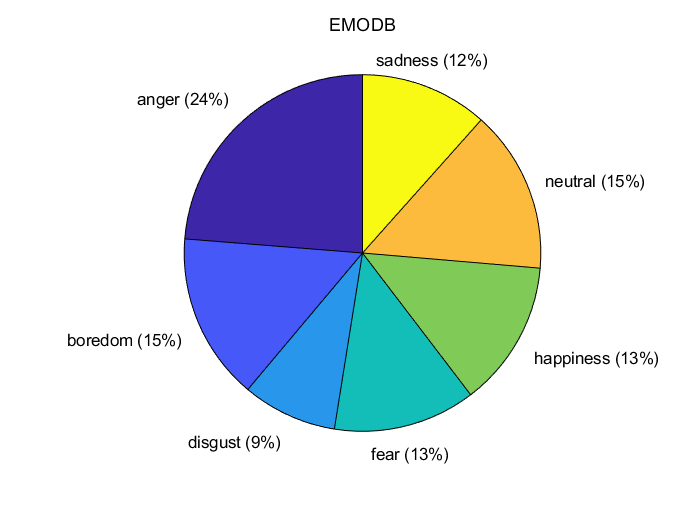

pie(audio_ds.Labels), title('EMODB');

- For each emotion, there are:

emotion_EMODB = categories(audio_ds.Labels)

emotion_EMODB = 7×1 cell 数组
    {'anger'    }
    {'boredom'  }
    {'disgust'  }
    {'fear'     }
    {'happiness'}
    {'neutral'  }
    {'sadness'  }


EMODB_anger = sum(audio_ds.Labels == 'anger')

EMODB_anger = 127

EMODB_boredom = sum(audio_ds.Labels == 'boredom')

EMODB_boredom = 81

EMODB_disgust = sum(audio_ds.Labels == 'disgust')

EMODB_disgust = 46

EMODB_fear = sum(audio_ds.Labels == 'fear')

EMODB_fear = 69

EMODB_happiness = sum(audio_ds.Labels == 'happiness')

EMODB_happiness = 71

EMODB_neutral = sum(audio_ds.Labels == 'neutral')

EMODB_neutral = 79

EMODB_sadness = sum(audio_ds.Labels == 'sadness')

EMODB_sadness = 62

## For RAVDESS

audio_data_path = '/Users/Y.H.Tian/Desktop/学习/UOG/Msc Project/code/database/RAVDESS_16000';           % get the path of audios in the chosen database
audio_ds = audioDatastore(audio_data_path,'FileExtensions','.wav');                                 % make a datastore for all the audios in such path (like a index of all files)

reset(audio_ds);                                        % reset(ds) resets the datastore specified by ds to the state where no data has been read from it. 

audio_ds = put_emotion_labels(audio_ds);      % Put Emotion Lables on it
audio_ds.Labels = categorical(audio_ds.Labels);

- There are these many files in RAVDESS:

length (audio_ds.Files)

ans = 1440

-  The pie chart is:

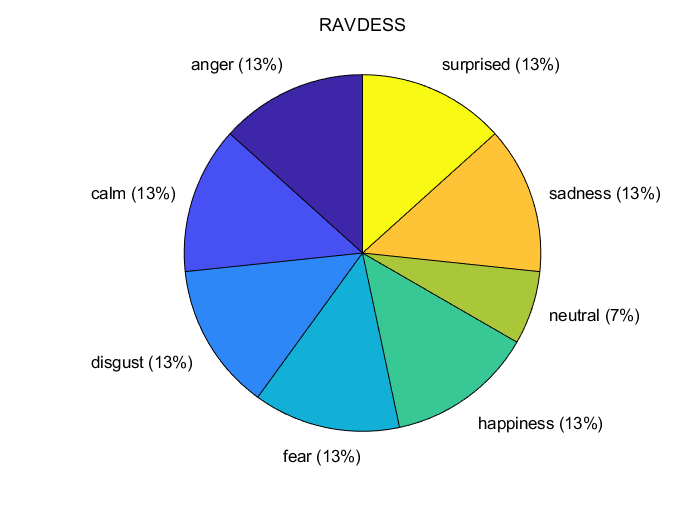

pie(audio_ds.Labels), title('RAVDESS');

- For each emotion, there are:

emotion_RAVDESS = categories(audio_ds.Labels)

emotion_RAVDESS = 8×1 cell 数组
    {'anger'    }
    {'calm'     }
    {'disgust'  }
    {'fear'     }
    {'happiness'}
    {'neutral'  }
    {'sadness'  }
    {'surprised'}


RAVDESS_anger = sum(audio_ds.Labels == 'anger')

RAVDESS_anger = 192

RAVDESS_calm = sum(audio_ds.Labels == 'calm')

RAVDESS_calm = 192

RAVDESS_disgust = sum(audio_ds.Labels == 'disgust')

RAVDESS_disgust = 192

RAVDESS_fear = sum(audio_ds.Labels == 'fear')

RAVDESS_fear = 192

RAVDESS_happiness = sum(audio_ds.Labels == 'happiness')

RAVDESS_happiness = 192

RAVDESS_neutral = sum(audio_ds.Labels == 'neutral')

RAVDESS_neutral = 96

RAVDESS_sadness = sum(audio_ds.Labels == 'sadness')

RAVDESS_sadness = 192

RAVDESS_surprised = sum(audio_ds.Labels == 'surprised')

RAVDESS_surprised = 192

## For SAVEE

audio_data_path = '/Users/Y.H.Tian/Desktop/学习/UOG/Msc Project/code/database/SAVEE_16000';           % get the path of audios in the chosen database
audio_ds = audioDatastore(audio_data_path,'FileExtensions','.wav');                                 % make a datastore for all the audios in such path (like a index of all files)

reset(audio_ds);                                        % reset(ds) resets the datastore specified by ds to the state where no data has been read from it. 



audio_ds = put_emotion_labels(audio_ds);      % Put Emotion Lables on it
audio_ds.Labels = categorical(audio_ds.Labels);

- There are these many files in SAVEE:

length (audio_ds.Files)

ans = 420

-  The pie chart is:

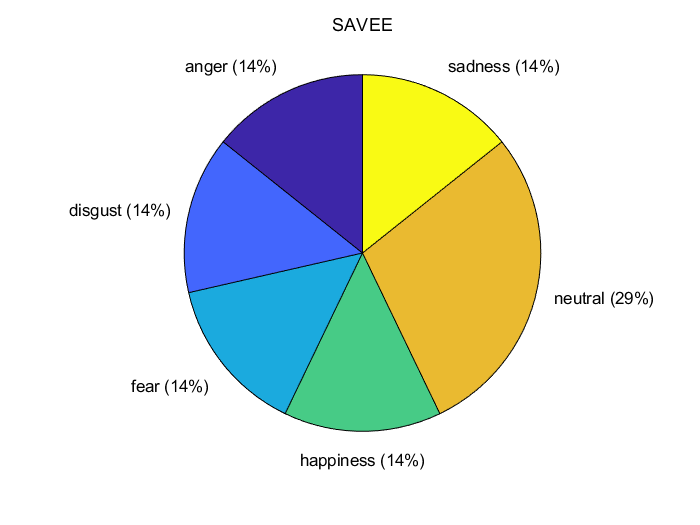

pie(audio_ds.Labels), title('SAVEE');

- For each emotion, there are:

emotion_SAVEE = categories(audio_ds.Labels)

emotion_SAVEE = 6×1 cell 数组
    {'anger'    }
    {'disgust'  }
    {'fear'     }
    {'happiness'}
    {'neutral'  }
    {'sadness'  }


SAVEE_anger = sum(audio_ds.Labels == 'anger')

SAVEE_anger = 60

SAVEE_calm = sum(audio_ds.Labels == 'calm')

SAVEE_calm = 0

SAVEE_disgust = sum(audio_ds.Labels == 'disgust')

SAVEE_disgust = 60

SAVEE_fear = sum(audio_ds.Labels == 'fear')

SAVEE_fear = 60

SAVEE_happiness = sum(audio_ds.Labels == 'happiness')

SAVEE_happiness = 60

SAVEE_neutral = sum(audio_ds.Labels == 'neutral')

SAVEE_neutral = 120

SAVEE_sadness = sum(audio_ds.Labels == 'sadness')

SAVEE_sadness = 60

SAVEE_surprised = sum(audio_ds.Labels == 'surprised')

SAVEE_surprised = 0